% Pharmakokinetik in der Anästhesie
clear all;

% 1. Zielkonzentration und Flussraten

% Zielkonzentration: 5 mg/L +- 5%
css = 5;
% Abbaurate k : 0.3 min⁻¹
k = 0.3;
% Volumen des Verteilungsraums: 7 L
vd = 7;
% Konzentration des Anästhetikums in der Infusionslösung: 10 mg/ml
infusionsloesung = 10;
% Zeit zum Erreichen des Zielwerts: 3 Minuten
t = 3;
% Gesamtzeit der Medikamentenzufuhr: 25 Minuten
gesamt_t = 25;
% Schwellenwert für Einschlaf / Aufwachzeitpunkt: 1 mg/L
c_min = 1;

%  2. Berechnung der Anfangsflussrate

% Anfänglicher Pegel darf maximal 5 % über oder unter dem Zielwert des Pegels liegen
% 5% über dem Zielwert
css_max = css * 1.05

css_max = 5.2500

% 5% unter dem Zielwert
css_min = css * 0.95

css_min = 4.7500

% Anfangsflussrate berechnen
% Quelle : https://med.libretexts.org/Bookshelves/Pharmacology_and_Neuroscience/Book%3A_Principles_of_Pharmacology_(Rosow_Standaert_and_Strichartz)/01%3A_Chapters/1.03%3A_Pharmacokinetics_I
% Da die Konzentration des Medikaments durch folgende Formel berechnet wird
% C(t) = (R/Vd*k) * (1-e^-k*t), dann wird die Anfnagsflussrate wie folgt
% berechnet (unten):
R1 = css * k * vd / ((1 - exp(-k * t))) % R1 in mg/min

R1 = 17.6937

% Jetzt um Die Anfangsflussrate in ml/min umzurechnen dividieren wir R1
% durch die Konzentration des Anästhetikums in der Infusionslösung: 10 mg/ml
R1 = R1 / infusionsloesung

R1 = 1.7694

% Um die Zielkonzentration von 5 mg/L innerhalb von 3 Minuten zu erreichen,
% wurde die Anfangsflussrate R1 berechnet. Diese ergibt sich zu etwa 1,77 ml/min, was darauf hinweist,
% dass die Infusion mit dieser Rate durchgeführt werden muss, um schnell die gewünschte Konzentration im Blut zu erreichen.

% Berechnung der maximalen und minimalen Anfangsflussrate in ml/min
R1_max = (css_max * k * vd) / (infusionsloesung* (1 - exp(-k * t))) 

R1_max = 1.8578

R1_min = (css_min * k * vd) / (infusionsloesung* (1 - exp(-k * t))) 

R1_min = 1.6809

% jetzt können wir merken, dass R1 = 1.7694 liegt zwischen R1_max = 1.8578
% und R1_min = 1.6809 

% 3. Berechnung der Erhaltungsflussrate
% Da die Erhaltungsflussrate (R2) ist was nötwendig um die konstante
% Konzentration eines Medikaments zu berechnen, betrachten wir der folgende
% Formel : Css= R2 / Cl  Quelle( section 1.3.19) https://med.libretexts.org/Bookshelves/Pharmacology_and_Neuroscience/Book%3A_Principles_of_Pharmacology_(Rosow_Standaert_and_Strichartz)/01%3A_Chapters/1.03%3A_Pharmacokinetics_I
% Cl = k * vd
% Jetzt um Die Erhaltungsflussrate in ml/min umzurechnen dividieren wir R2
% durch die Konzentration des Anästhetikums in der Infusionslösung: 10 mg/ml
R2 = css * k * vd / infusionsloesung

R2 = 1.0500

% Modellieren Sie die Konzentration des Medikaments in drei Phasen und erläutern Sie die
% mathematischen Modelle für diese Phasen
% 1. Anfangsinfusion: Von Zeit 0 bis 3 Minuten mit der Flussrate R1.
% Zeit von 0 bis 3
phase1_t = 0:3;
% die Konzentration des Medikaments in dieser Zeit (0 bis 3 min) 
R1 = R1 * infusionsloesung; % R1 wieder in mg/min umrechnens
R2 = R2 * infusionsloesung; % R2s wieder in mg/min umrechnens

phase1_Konzentration = (R1/(k * vd)) * (1 - exp(-k * phase1_t));
% 2. Erhaltungsinfusion: Von 3 bis 25 Minuten mit der Flussrate R2.
% Zeit von 3 bis 25
phase2_t = 3:25;
% die Konzentration des Medikaments in dieser Zeit (3 bis 25 min) 
% Die Formel bestimmt die Medikamentenkonzentration während der Erhaltungsinfusion (Phase 2).
% C_ss ist die Zielkonzentration, erreicht nach der Anfangsinfusion.
% Die Flussraten R2 und R1 für die Erhaltungs- bzw. Anfangsphase beeinflussen,
% ob die Konzentration steigt oder fällt ( in diesem Fall sinkt, da R2 kleiner als R1).
% Der Exponentialterm beschreibt die Anpassung der Konzentration an die geänderte Flussrate. 
% Diese Formel ist aus der Analyse des Übergangs von der Anfangs- zur Erhaltungsinfusion entstanden.
phase2_Konzentration = css + (R2 - R1) * (1 - exp(-k * (phase2_t - t))) / (k * vd);

% 3. Nach Abschalten der Infusion: Nach 25 Minuten, wenn die Infusion abgestellt wird.
% Zeit von 3 bis 25
phase3_t = 25:100;
% die Konzentration des Medikaments in dieser Zeit (3 bis 25 min) 
% jetzt wird die Konzentration Nach Abschalten der Infusion berechnet mit
% der Formel aus (1.3.7)
% Quelle : https://med.libretexts.org/Bookshelves/Pharmacology_and_Neuroscience/Book%3A_Principles_of_Pharmacology_(Rosow_Standaert_and_Strichartz)/01%3A_Chapters/1.03%3A_Pharmacokinetics_I
phase3_Konzentration = phase2_Konzentration(23) * exp(-k * (phase3_t - gesamt_t));
% Berechnen Sie die Zeit, die benötigt wird, bis die Medikamentenkonzentration nach Beginn der Infusion
% über den Schwellenwert C_min fällt. (Einschlafzeit)
% Bestimmung der Einschlafzeit 
% Die Einschlafzeit ist die Zeit, die das Medikament nach Beginn der Infusion braucht,
% um eine bestimmte Konzentration im Körper zu erreichen, nämlich 1 mg/L. Um diese Zeit zu berechnen, 
% wird die Formel, die beschreibt, wie sich die Medikamentenkonzentration entwickelt, 
% so umgestellt, dass man die Zeit t erhält, bei der diese Konzentration von 1 mg/L (C_min) erreicht wird.
syms tEA;
% nach t auflösen
einschlafzeit = solve(R1/ (k * vd) * (1 - exp(-k * tEA))  == c_min, tEA)

$$einschlafzeit = -\frac{10\,\log\left(\frac{2090117421039157}{2371592397749813}\right)}{3}$$


einschlafzeit = double(einschlafzeit)

einschlafzeit = 0.4211

% Berechnen Sie die Zeit, die benötigt wird, bis die Medikamentenkonzentration nach Abschalten der
% Infusion unter den Schwellenwert C_min fällt. (Aufwachzeit). Die Infusion wird nach 25 Minuten
% abgestellt.
% Nach dem Abschalten der Infusion sinkt die Konzentration des Medikaments
% exponentiell ab, d.h. dafür nutzen wir die Gleichung für die Berechnung
% der Konzentration nach Abschalten der Infusionm und lösen wir diese
% Gleichung nach t
% Bestimmung der Aufwachzeit 
aufwachzeit = solve(phase2_Konzentration(23) * exp(-k * (tEA - gesamt_t)) == c_min, tEA)

$$aufwachzeit = 25-\frac{10\,\log\left(\frac{2251799813685248}{3555752480354429}\right)}{3}$$

aufwachzeit = double(aufwachzeit)

aufwachzeit = 26.5228

% Bestimmen Sie den nach 3 Minuten erreichten Pegel, was die
% Medikamentenkonzentration in diesem Zeitpunkt entspricht, also am Ende
% der Anfangsinfusion-Phase
pegel_3min = (R1 * (1 - exp(-k * 3))) / (k * vd)

pegel_3min = 5.0000

% Bestimmen Sie den maximal erreichten Pegel, was die
% höchste Medikamentenkonzentration im Blut, die während der gesamten Zeit
% und dies ist gleich den 3 Minuten erreichten Pegel, da dies die höchste Konzentration ist, 
% bevor die Infusion in eine niedrigere Erhaltungsflussrate übergeht.
pegel_max = pegel_3min

pegel_max = 5.0000

% Bestimmen Sie das gesamte infundierte Volumen. 
% Das gesamtinfundierte Volumen ist die gesamte Menge an Medikamentenlösung,
% die während der gesamten Infusionszeit in den Körper des Patienten gegeben wird.
% Da die Gesamte Zeit 25 min ist und die Infusionszeit besteht aus zwei
% Phasen (AnfangsInfusion-Phase und ErhaltungsInfusion-Phase), dann das
% gesamte infundierte Volumen ist die Addition von das infundierte Volumen
% in Phase-1  und von das infundierte Volumen in Phase-2
% um das Volumen zu berechnen, nutzen wir die folgende Formel : R = Vd/td
% https://pressbooks.online.ucf.edu/osuniversityphysics/chapter/14-5-fluid-dynamics/
t = 3;
% Das infundierte Volumen in Phase-1
v1 = (R1/10) * t

v1 = 5.3081

% Das infundierte Volumen in Phase-2
% zweite phase von 3 bis 25 also 22 min (25 - 3)
v2 = (R2/10) * (gesamt_t - t)

v2 = 23.1000

% Das gesamte infundierte Volumen 
gesamt_v  = v1 + v2

gesamt_v = 28.4081

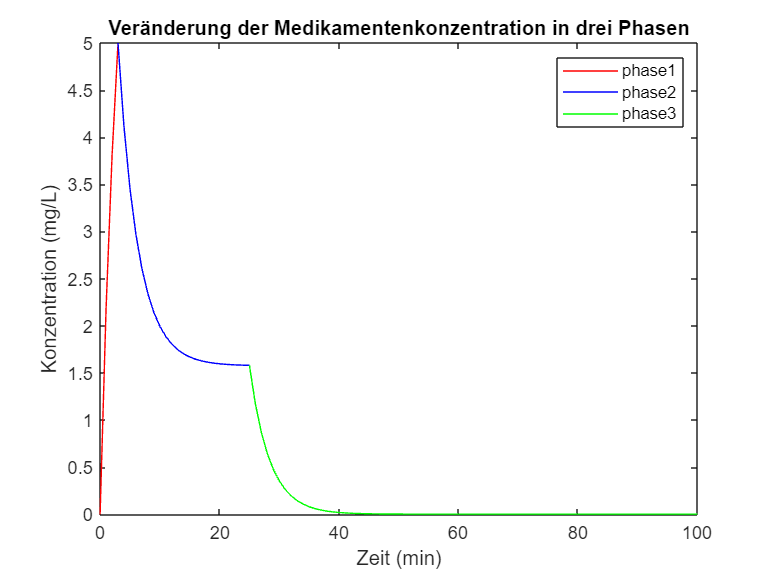

% Erkläreung der Verlauf
% Zunächst (0 bis 3 Minuten): Wird das Medikament schnell auf die Zielkonzentration gebracht, 
% indem eine hohe Flussrate R1 verwendet wird. 
% Anschließend (3 bis 25 Minuten): Wird die Konzentration durch die Erhaltungsflussrate R2 auf einem stabilen Niveau gehalten.
% Nach dem Stoppen der Infusion: Beginnt die Konzentration, durch den Abbau des Medikaments zu sinken.
figure;
% plot der Konzentration des Medikamentes in der erste Phase von 0 bis 3 min
plot(phase1_t, phase1_Konzentration, 'r');
hold on;
% plot der Konzentration des Medikamentes in der zweite Phase von 3 bis 25 min
plot(phase2_t, phase2_Konzentration, 'b');
hold on;
% plot der Konzentration des Medikamentes in der dritte Phase Nach Abschalten der Infusion
plot(phase3_t, phase3_Konzentration, 'g');
xlabel('Zeit (min)');
ylabel('Konzentration (mg/L)');
title('Veränderung der Medikamentenkonzentration in drei Phasen');
legend('phase1', 'phase2', 'phase3');

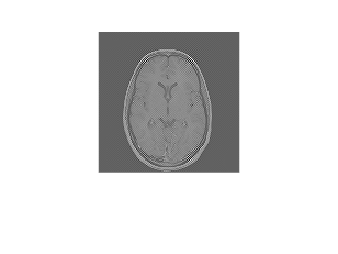



% Gefilterte Rückprojektion
% 1. Laden Sie das bereitgestellte CT-Bild mit Artefakt und stellen Sie es dar.
ctBild = imread('ct_slice_artifact.png');
figure;
% gelesene Bild anzeigen
imshow(ctBild);

% 2. Berechnen Sie die Fourier-Transformation des CT-Bildes mit Artefakt und atellen Sie diese dar.
% 2D-Fourier-Transformation
% das CT-Bild wird in den Frequenzbereich umgewandelt.
transformiertes_bild = fft2(ctBild);
% Verschiebt die Nullfrequenz in die Mitte des Frequenzspektrums.
transformiertes_bild = fftshift(transformiertes_bild);
figure;
% die Fourier-Transformation des CT-Bildes darstellen
imshow(transformiertes_bild);

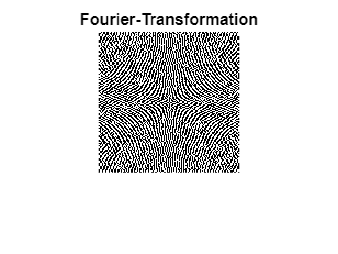

title('Fourier-Transformation');


% 3. Erstellen Sie einen geeigneten Ram-Lak-Filter für das Bild. 

% Anzahl der Zeilen und Spalten im Bild
[zeilen, spalten] = size(ctBild);

% Ram-Lak-Filter erstellen
frequenz = linspace(-0.5, 0.5, zeilen)  % Normalisierte Frequenzen

frequenz =    -0.5000   -0.4921   -0.4843   -0.4764   -0.4685   -0.4606   -0.4528   -0.4449   -0.4370   -0.4291   -0.4213   -0.4134   -0.4055   -0.3976   -0.3898   -0.3819   -0.3740   -0.3661   -0.3583   -0.3504   -0.3425   -0.3346   -0.3268   -0.3189   -0.3110   -0.3031   -0.2953   -0.2874   -0.2795   -0.2717   -0.2638   -0.2559   -0.2480   -0.2402   -0.2323   -0.2244   -0.2165   -0.2087   -0.2008   -0.1929   -0.1850   -0.1772   -0.1693   -0.1614   -0.1535   -0.1457   -0.1378   -0.1299   -0.1220   -0.1142


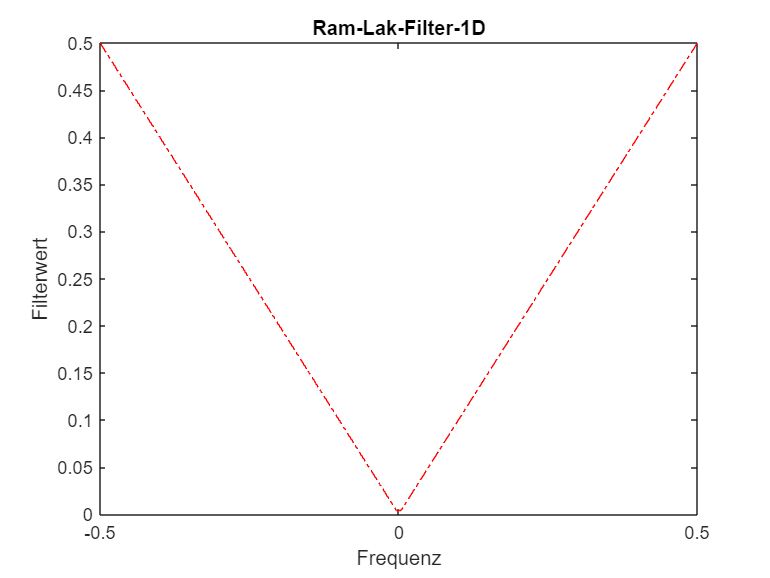


% Ram-Lak-Filter im Frequenzraum (Betrag, um das Vorzeichen von alle
% Negativen Werte zu wechseln)
ram_lak = abs(frequenz); 

% Darstellung des Ram-Lak-Filters (1D)
figure;
plot(frequenz, ram_lak, 'r-.');
title('Ram-Lak-Filter-1D');
xlabel('Frequenz');
ylabel('Filterwert');

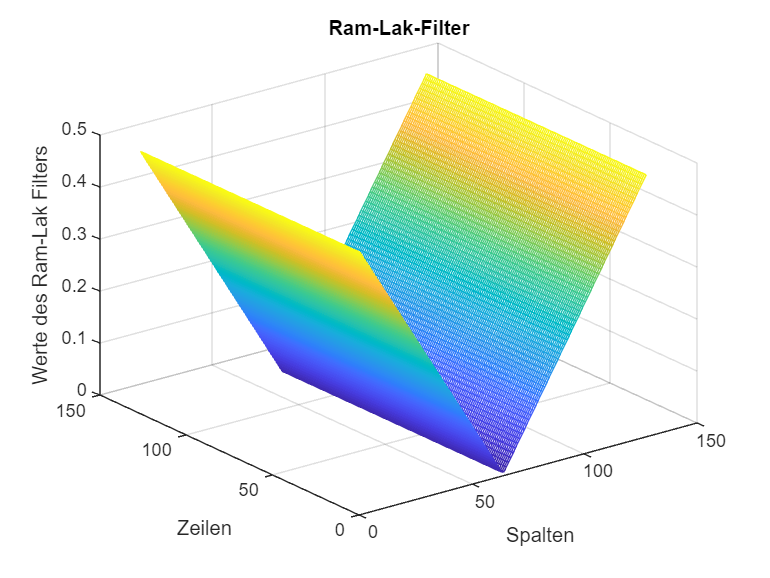


% Erweitern des Filters auf die Bildgröße
% Der Ram-Lak-Filter wird zuerst als 1D-Vektor erstellt, 
% um die Frequenzteile im Bild zu beeinflussen. Um ihn auf das gesamte 2D-Fourier-Bild anzuwenden,
% muss dieser 1D-Filter auf alle Zeilen des Bildes ausgeweitet werden.
% Damit wird der 1D-Filter in jeder Zeile wiederholt, sodass eine 2D-Matrix entsteht, 
% die den Filter gleichmäßig auf das gesamte Bild anwendet.
ram_lak = repmat(ram_lak, zeilen, 1); 

% 4. Stellen Sie den Ram-Lak-Filter grafisch dar. 

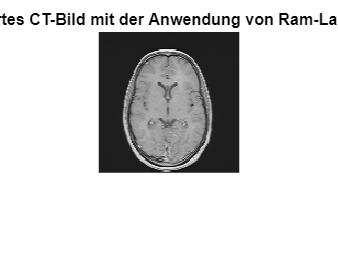

% Grafische Darstellung des Ram-Lak Filters
figure;
mesh(ram_lak);
xlabel('Spalten');
ylabel('Zeilen');
zlabel('Werte des Ram-Lak Filters');
title('Ram-Lak-Filter');
grid on;


% 5. Wenden Sie den Ram-Lak-Filter im Fourier-Raum auf die transformierten Daten an.
% Filter multiplizieren
ram_lak_FR = fftshift(transformiertes_bild) .* ram_lak;

% 6. Transformieren Sie das gefilterte Bild zurück in den Bildraum und stellen Sie dieses dar. 
% Rücktransformation bilden
gefiltertes_ctBild = ifft2(ifftshift(ram_lak_FR));

% Betrag, um alle negative Werte zu postive Werte zu wechseln, da jedes
% Pixel im Bild einen Wert grösser gleich 0 hat
gefiltertes_ctBild = abs(gefiltertes_ctBild); 

% gefiltertes Bild anzeigen
figure;
imshow(gefiltertes_ctBild, []);
title('gefiltertes CT-Bild mit der Anwendung von Ram-Lak Filter');

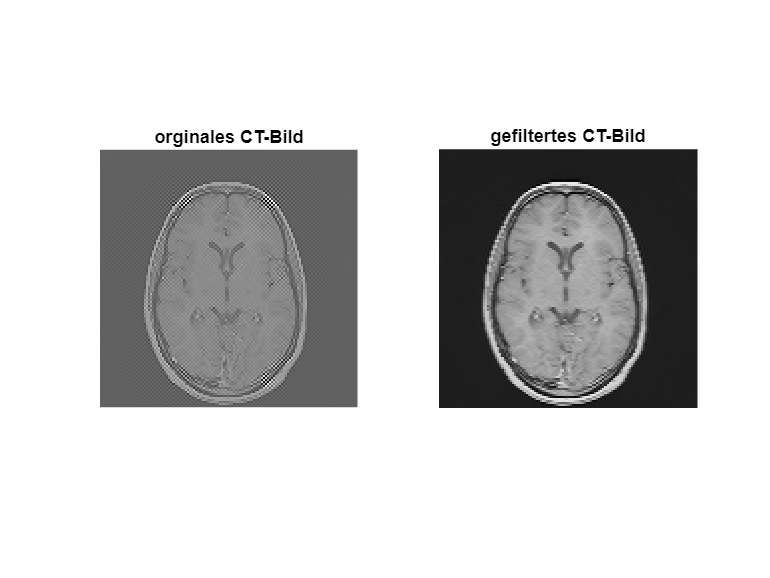


% 7. Stellen Sie die Differenz zwischen dem gefilterten Bild und dem Bild mit Artefakt dar.
% Diskutieren Sie das Ergebnis. 
figure;
subplot(1,2,1)
imshow(ctBild)
title('orginales CT-Bild')
subplot(1,2,2)
imshow(gefiltertes_ctBild, [])
title('gefiltertes CT-Bild')

% Der Ram-Lak-Filter sorgt dafür, dass die Kanten in CT-Bildern schärfer und klarer werden und gleichzeitig die typischen Artefakte der ungefilterten Rückprojektion reduziert werden.
% Das Ergebnis ist eine präzisere Darstellung der anatomischen Strukturen.
% Allerdings hat der Filter auch den Nachteil, dass er hochfrequentes Rauschen verstärkt, was im gefilterten Bild deutlicher zu erkennen ist. 
% Diese Verstärkung kann die Bildlesbarkeit erschweren. 

% verwendet Quellen für Ram-Lak Filter
% (stackoverflow Ram-Lak implementieren) https://stackoverflow.com/questions/6709871/matlab-how-to-implement-a-ram-lak-filter-ramp-filter-in-the-frequency-domain
% Ultraschall-ComputerTomographi (pdf)

















